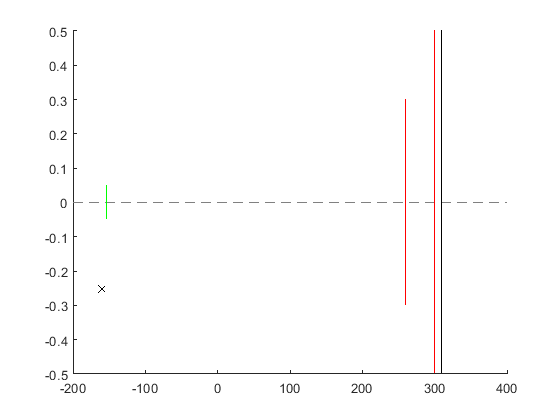

addpath("functionsAndGUI\")
tic

%plot setup with
beamon=false;

%Goebel specification
NRays=200; %number of rays per source
Ngoebel=1; %Number of sources on Goebel mirror

delta=0.04; %divergence angle
fwhm=1.35; %fwhm of Goebel source distr.
ds=160; %distance to sources on sarm
dgoebelsslit=7; %distance Goebel to source slit
gammas=90; %Goebel mirror rotation [deg] (90=not rotated)



%slit specifications
wsslit=0.1; %width source slit
wantisc=0.6; %width anti-scatter slit
wdslit=1; %width detector slit
dantisc=260; %distance antiscatter slit on darm
ddslit=300; %distance detector slit on darm

%detector speficications
dd=310;
wd=1;
NPixels=100;

%Tube Scan specifications
beta=0; %Detector arm angle
alpha_min=-0.15;
alpha_max=0.15;
incr=0.003;


%item angles
gammasslit=90; gammadslit=90; gammaantisc=90; gammad=90;
%item calculations
dsslit=ds-dgoebelsslit;

%Create setup
setup=startsetup();

setup=add_goebel(setup,ds,gammas,fwhm,Ngoebel,NRays,delta);
setup=add_sslit(setup,dsslit,wsslit, gammasslit);
setup=add_dslit(setup,dantisc,wantisc,gammaantisc);
setup=add_dslit(setup,ddslit,wdslit,gammadslit);
setup=add_detector(setup,dd,wd, gammad,NPixels);


%plot basic, non-rotated setup with beams off or on depending on beamon
fig1=plot_setup(setup,0,0,beamon,dd+1);


%TubeScan
[alpha,J]=Scan_Tube(setup,alpha_min,alpha_max,incr,beta);

ans = -0.1500

ans = -0.1470

ans = -0.1440

ans = -0.1410

ans = -0.1380

ans = -0.1350

ans = -0.1320

ans = -0.1290

ans = -0.1260

ans = -0.1230

ans = -0.1200

ans = -0.1170

ans = -0.1140

ans = -0.1110

ans = -0.1080

ans = -0.1050

ans = -0.1020

ans = -0.0990

ans = -0.0960

ans = -0.0930

ans = -0.0900

ans = -0.0870

ans = -0.0840

ans = -0.0810

ans = -0.0780

ans = -0.0750

ans = -0.0720

ans = -0.0690

ans = -0.0660

ans = -0.0630

ans = -0.0600

ans = -0.0570

ans = -0.0540

ans = -0.0510

ans = -0.0480

ans = -0.0450

ans = -0.0420

ans = -0.0390

ans = -0.0360

ans = -0.0330

ans = -0.0300

ans = -0.0270

ans = -0.0240

ans = -0.0210

ans = -0.0180

ans = -0.0150

ans = -0.0120

ans = -0.0090

ans = -0.0060

ans = -0.0030

ans = 0

ans = 0.0030

ans = 0.0060

ans = 0.0090

ans = 0.0120

ans = 0.0150

ans = 0.0180

ans = 0.0210

ans = 0.0240

ans = 0.0270

ans = 0.0300

ans = 0.0330

ans = 0.0360

ans = 0.0390

ans = 0.0420

ans = 0.0450

ans = 0.0480

ans = 0.0510

ans = 0.0540

ans = 0.0570

ans = 0.0600

ans = 0.0630

ans = 0.0660

ans = 0.0690

ans = 0.0720

ans = 0.0750

ans = 0.0780

ans = 0.0810

ans = 0.0840

ans = 0.0870

ans = 0.0900

ans = 0.0930

ans = 0.0960

ans = 0.0990

ans = 0.1020

ans = 0.1050

ans = 0.1080

ans = 0.1110

ans = 0.1140

ans = 0.1170

ans = 0.1200

ans = 0.1230

ans = 0.1260

ans = 0.1290

ans = 0.1320

ans = 0.1350

ans = 0.1380

ans = 0.1410

ans = 0.1440

ans = 0.1470

ans = 0.1500


toc

Elapsed time is 0.917399 seconds.
